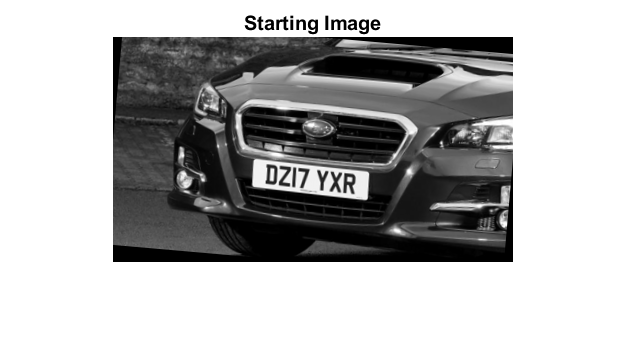

% Load the image
f = imread("car_images\Good_img/working/Cars3.png");

figure
imshow(f)
title('Starting Image');

img = im2double(rgb2gray(f)); %convert image to greyscale
img = imrotate(img, -5, 'bilinear', 'crop'); %rotate the image slightly to reduce the chance of exact horizontal lines



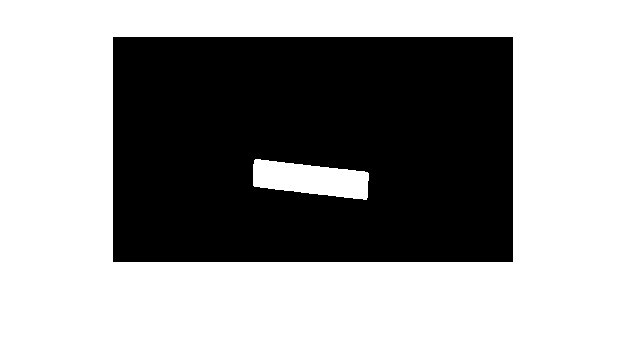

fourcorners = 4×2 single matrix
  143.5571  123.2385
  255.3684  136.9606
  253.0000  163.0000
  141.3786  148.3635


output = getCornersLicense(img); % Get 4 input points from the 'getcornersLicence' function (see bottom of the code)

xi = output(:,1);
yi = output(:,2);

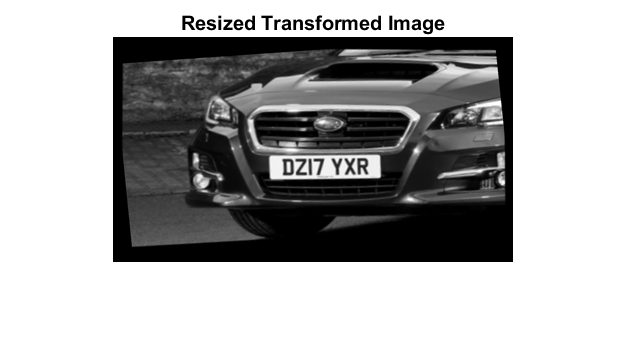


% Define the base points for the transformation
base = [1 1; 1 size(img, 1); size(img, 2) 1; size(img, 2) size(img, 1);];

% Compute the homography transform
tf = fitgeotrans([xi, yi], base, 'projective');
H = tf.T;

% Perform the homography transformation
[xf, xf_ref] = imwarp(img, tf);

% Specify the desired width and height of the output image (in pixels)
desired_width = size(img, 2);
desired_height = size(img, 1);

% Resize the output image while maintaining its aspect ratio
xf_resized = imresize(xf, [desired_height, desired_width]);

% Display the resized transformed image
figure;
imshow(xf_resized);
hold on;
title('Resized Transformed Image');

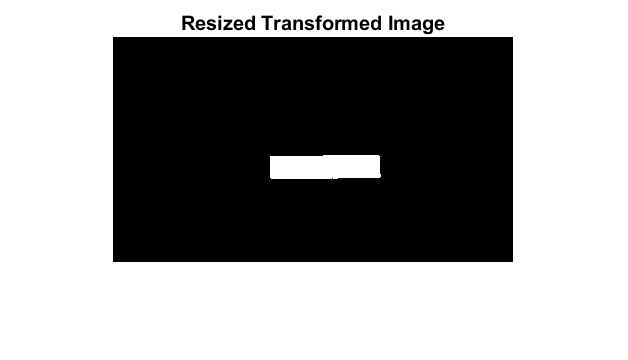

fourcorners = 4×2 single matrix
  265.5000  119.5000
  267.2440  139.0945
  223.0171  142.0171
  158.0000  120.0000


% Get the corners of the resized/transformed image 
corners = getCornersLicense(xf_resized);

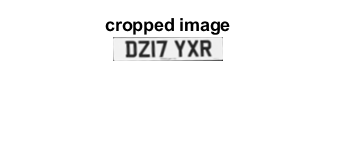


min_x = floor(min(corners(:, 1)));
max_x = floor(max(corners(:, 1)));
min_y = floor(min(corners(:, 2)));
max_y = floor(max(corners(:, 2)));

% Construct the rectangle vector for cropping the image
RECT = [min_x, min_y, max_x - min_x, max_y - min_y];

cropped = imcrop(xf_resized,RECT);

figure
imshow(cropped)
title('cropped image')

% Recognise the text
%ocrResults = ocr(cropped);
%recognizedText = ocrResults.Text 

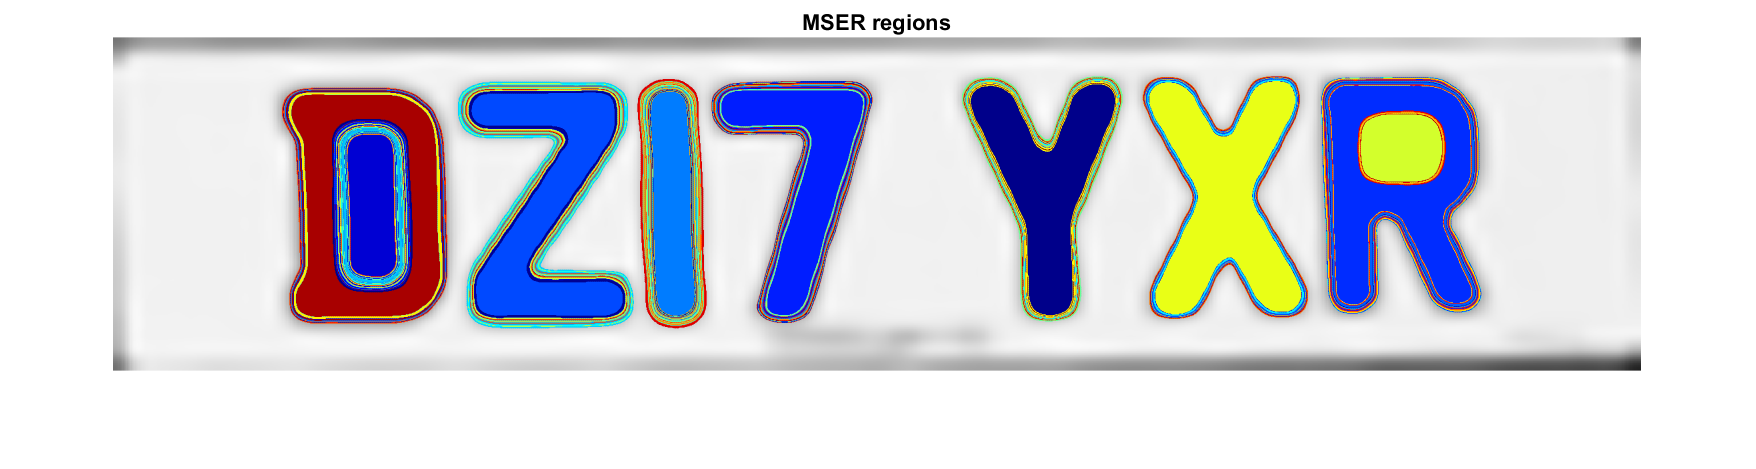

%% SEGEMENTING LETTERS
I = imresize(cropped,[500 NaN]); %resize so the number of rows of pixels is 500. 
%The number of columns is automatically calculated based on aspect ratio

% Detect MSER regions. 
[mserRegions, mserConnComp] = detectMSERFeatures(I, ... 
    "RegionAreaRange",[10000 60000],"ThresholdDelta",5);

%Shwoing the image with MSER regions
figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("MSER regions")
hold off

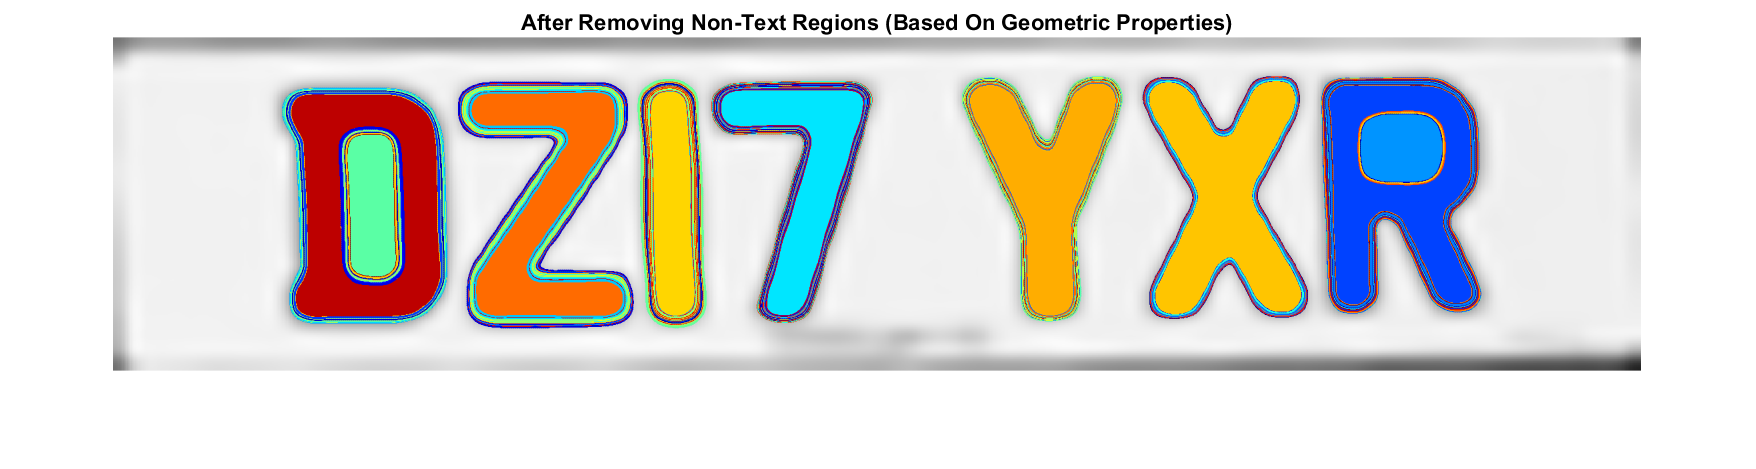


% Use regionprops (region properties) to measure MSER properties
mserStats = regionprops(mserConnComp, "BoundingBox", "Eccentricity", ...
    "Solidity", "Extent", "Euler", "Image");

% Compute the aspect ratio using bounding box data.
bbox = vertcat(mserStats.BoundingBox);
w = bbox(:,3);
h = bbox(:,4);
aspectRatio = w./h;

% Threshold the data to determine which regions to remove. These thresholds
% may need to be tuned for other images.
filterIdx = aspectRatio' > 3; 
filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
filterIdx = filterIdx | [mserStats.Solidity] < .3;
filterIdx = filterIdx | [mserStats.Extent] < 0.2 | [mserStats.Extent] > 0.9;
filterIdx = filterIdx | [mserStats.EulerNumber] < -4;

% Remove regions
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

% Show remaining regions
figure
imshow(I)
hold on
plot(mserRegions, "showPixelList", true,"showEllipses",false)
title("After Removing Non-Text Regions (Based On Geometric Properties)")
hold off

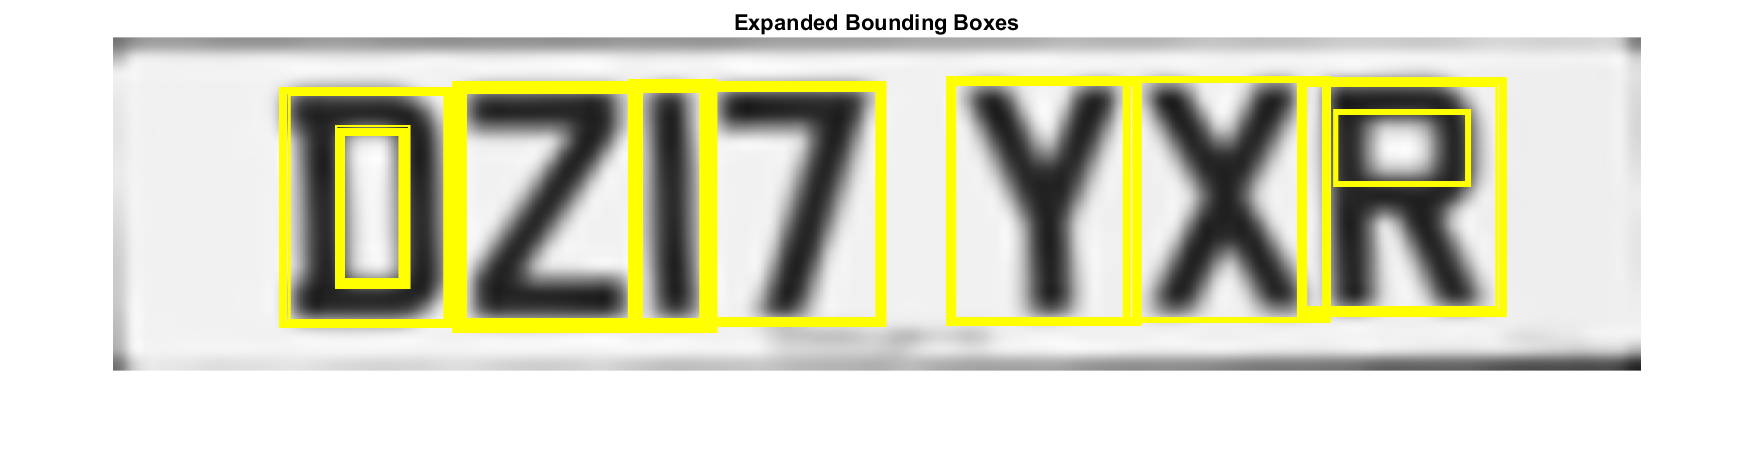


%----------------

% Get bounding boxes for all the regions
bboxes = vertcat(mserStats.BoundingBox);

% Convert from the [x y width height] bounding box format to the [xmin ymin
% xmax ymax] format for convenience.
xmin = bboxes(:,1);
ymin = bboxes(:,2);
xmax = xmin + bboxes(:,3) - 1;
ymax = ymin + bboxes(:,4) - 1;

% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;

% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(I,2));
ymax = min(ymax, size(I,1));

% Show the expanded bounding boxes
expandedBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
IExpandedBBoxes = insertShape(I,"rectangle",expandedBBoxes,"LineWidth",3);

figure
imshow(IExpandedBBoxes)
title("Expanded Bounding Boxes")

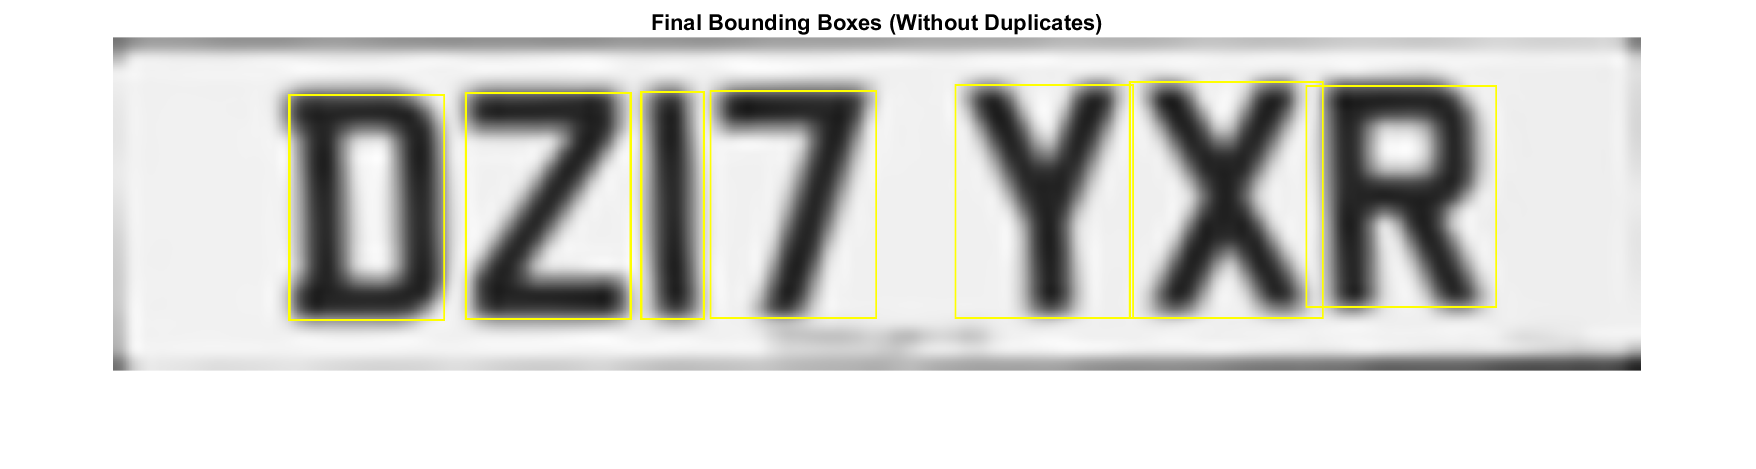


%-------------

% Initialize an empty array to store indices of unique bounding boxes
uniqueIndices = [];

% Calculate the area of each bounding box
areas = (xmax - xmin + 1) .* (ymax - ymin + 1);

% Iterate over each bounding box
for i = 1:size(expandedBBoxes, 1)
    % Flag to indicate if current bounding box is unique
    isUnique = true;
    
    % Iterate over already identified unique bounding boxes
    for j = 1:length(uniqueIndices)
        % Calculate intersection area
        x_overlap = max(0, min(xmax(i), xmax(uniqueIndices(j))) - max(xmin(i), xmin(uniqueIndices(j))));
        y_overlap = max(0, min(ymax(i), ymax(uniqueIndices(j))) - max(ymin(i), ymin(uniqueIndices(j))));
        intersection_area = x_overlap * y_overlap;
        
        % Calculate area ratio (intersection over min area)
        area_ratio = intersection_area / min(areas(i), areas(uniqueIndices(j)));
        
        % If area ratio is above a threshold, consider the bounding box duplicate
        if area_ratio > 0.5 % Adjust threshold as needed
            isUnique = false;
            break;
        end
    end
    
    % If current bounding box is unique, add its index to uniqueIndices
    if isUnique
        uniqueIndices = [uniqueIndices, i];
    end
end

% Extract unique bounding boxes
uniqueBBoxes = expandedBBoxes(uniqueIndices, :);

% Show the final bounding boxes after removing duplicates
IFinalBBoxes = insertShape(I, "rectangle", uniqueBBoxes, "LineWidth", 3);

figure
imshow(IFinalBBoxes)
title("Final Bounding Boxes (Without Duplicates)")

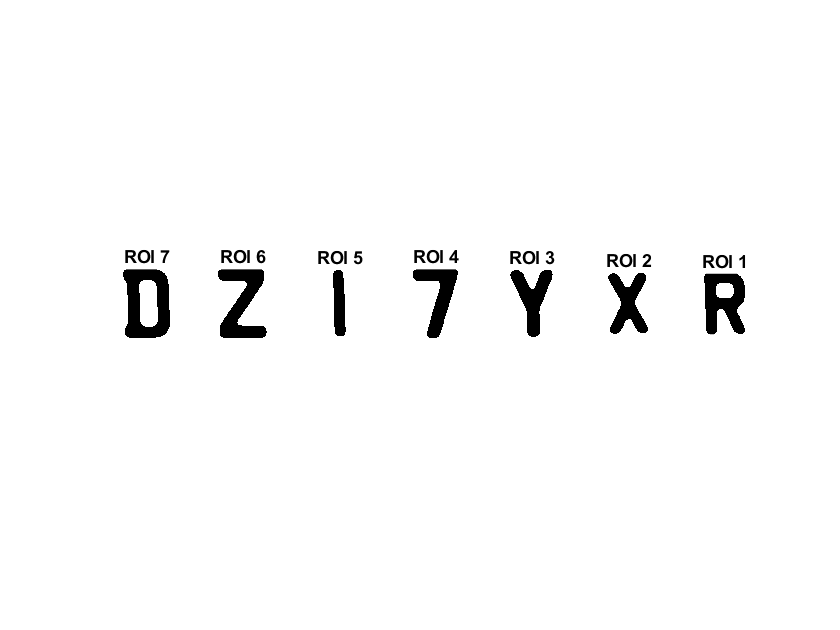


%---------------------

% Initialize cell array to store individual letter ROIs and their corresponding bounding boxes
letterROIs = cell(size(uniqueBBoxes, 1), 1);
orderedBBoxes = uniqueBBoxes; % Copy bounding boxes for sorting

% Sort bounding boxes by their x-coordinates (xmin) This is so they are
% read and displayed in the correct order
[~, order] = sort(orderedBBoxes(:, 1));
orderedBBoxes = orderedBBoxes(order, :);

% Iterate over each bounding box
for i = 1:size(orderedBBoxes, 1)
    % Extract ROI using bounding box coordinates
    xmin = orderedBBoxes(i, 1);
    ymin = orderedBBoxes(i, 2);
    width = orderedBBoxes(i, 3);
    height = orderedBBoxes(i, 4);
    roi = imcrop(I, [xmin, ymin, width, height]);
    
    roi = imresize(roi,[400,NaN]); % resize the image to height 400px
    roi = imbinarize(roi); % Binarize the image
   
    
    % Define the desired dimensions for the resized image
    desired_height = 400;
    desired_width = 300; 

    % Calculate the padding amounts for each side
    pad_height = max(0, desired_height - size(roi, 1));
    pad_width = max(0, desired_width - size(roi, 2));
    pad_top = floor(pad_height / 2);
    pad_bottom = ceil(pad_height / 2);
    pad_left = floor(pad_width / 2);
    pad_right = ceil(pad_width / 2);

    % Pad the image evenly around the whole image with ones
    padded_image = padarray(roi, [pad_top, pad_left], 1, 'pre');
    padded_image = padarray(padded_image, [pad_bottom, pad_right], 1, 'post');
  
    
    % Store preprocessed ROI
    letterROIs{i} = padded_image;
end

figure;

% Display each ROI in a subplot, in order of when they appear in the image
for i = 1:length(letterROIs)
    subplot(1, length(letterROIs), i);
    imshow(letterROIs{i})
    title(['ROI ' num2str(order(i))]); % Display ROIs in the original order
end

function sortedcorners = getCornersLicense(grayImg)
    %Binarize image and isolate the license plate
    f3 = imadjust(grayImg, [0.5 1], [0 1]);
    f3 = imbinarize(f3);
    f3 = imclearborder(f3);
    CC = bwconncomp(f3);
    
    numPixels = cellfun(@numel, CC.PixelIdxList);
    [biggest, idx] = max(numPixels);
    for k = 1:length(numPixels)
        if k ~= idx
            f3(CC.PixelIdxList{k}) = 0;
        end
    end

    % Hide the letters to get better corner detection
    f4 = imfill(f3, "holes");

    figure
    imshow(f4)
    title('Extracted Licence Plate Shape');

    % Detect the 4 corners of the license plate
    points = detectBRISKFeatures(f4);
    mainpoints = points.selectStrongest(30).Location;

    [toppoint, topidx] = min(mainpoints(:,2));
    [bottompoint, bottomidx] = max(mainpoints(:,2));
    [leftpoint, leftidx] = min(mainpoints(:,1));
    [rightpoint, rightidx] = max(mainpoints(:,1));
  
    fourcorners = [mainpoints(topidx,:); mainpoints(rightidx,:); mainpoints(bottomidx,:); mainpoints(leftidx,:)]

    rowSums = sum(fourcorners,2);
    % Sort the sums, obtaining the sorted indices
    [~, sortedIndices] = sort(rowSums);
    % Use the indices to reorder the matrix rows
    sortedcorners = fourcorners(sortedIndices, :);
end





